# 平均，標本分散と不偏分散

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;
rng(1);

平均1，分散1の正規分布からN個の標本を抽出する．

これをM回繰り返す．

N=10;M=1000;
v=zeros(M,2);
m=zeros(M,1)

m =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for n1=1:M
    x=normrnd(1,1,[N,1]);
    m(n1)=mean(x);

var関数は規定値では不変分散，二つ目の引数を1とすると標本分散を算出する

    v(n1,:)=[var(x) var(x,1)];
end

m個得られた標本平均のヒストグラムを描く

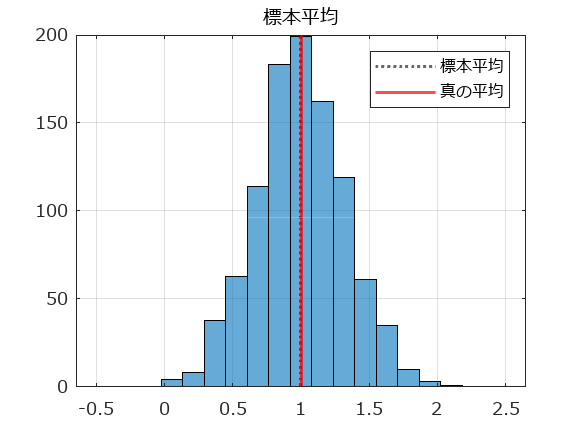

edges=linspace(-0.5,2.5,20);
figure
histogram(m,edges);grid on;
set(gca,'fontname','メイリオ');
title('標本平均');
hndl(1)=xline(mean(m),':','LineWidth',1.5);
hndl(2)=xline(1,'r-','LineWidth',1.5);
legend(hndl,{'標本平均','真の平均'});
ylabel('頻度');
exportgraphics(gcf,'fig_sampleMean.pdf');

M個ずつ得られた不変分散と標本分散の度数分布(ヒストグラム)を描く

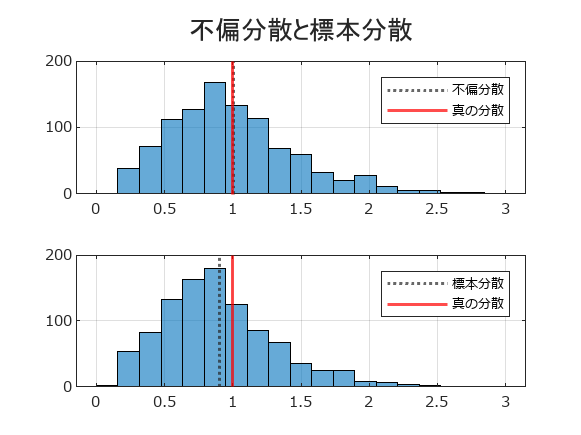

figure;tiledlayout(2,1);
nexttile;
edges=linspace(0,3,20);
histogram(v(:,1),edges);hold on;grid on;
set(gca,'fontname','メイリオ');
hndl(1)=xline(mean(v(:,1)),':','LineWidth',1.5);
hndl(2)=xline(1,'r-','LineWidth',1.5);
legend(hndl,{'不偏分散','真の分散'});

nexttile;
histogram(v(:,2),edges);hold on;grid on;
set(gca,'fontname','メイリオ')
hndl2(1)=xline(mean(v(:,2)),':','LineWidth',1.5);
hndl2(2)=xline(1,'r-','LineWidth',1.5);
legend(hndl2,{'標本分散','真の分散'});
sgtitle('不偏分散と標本分散','fontname','メイリオ');
exportgraphics(gcf,'fig_sampleVariance.pdf');

標本から算出された不変分散と標本分散，M回の平均

mean(v)

ans =     1.0020    0.9018
